# DC Motor Speed: State-Space Methods for Controller Design

clear
close all
J = 0.01;
b = 0.1;
K = 0.01;
R = 1;
L = 0.5;
A = [-b/J   K/J
    -K/L   -R/L];
B = [0
    1/L];
C = [1   0];
D = 0;
sys = ss(A,B,C,D)

sys =
 
  A = 
          x1     x2
   x1    -10      1
   x2  -0.02     -2
 
  B = 
       u1
   x1   0
   x2   2
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties


## Prueba de controlabilidad de los estados

sys_order = order(sys)

sys_order = 2

sys_rank = rank(ctrb(A,B))

sys_rank = 2

## Prueba de observabilidad de los estados

sys_rank = rank(obsv(A,C))

sys_rank = 2

#### Eligiendo los polos dominantes en lazo cerrado en:

p1 = -5 + 1i;
p2 = -5 - 1i;

Se satisfacen los requerimientos de diseño porcentaje sobre elongación y tiempo de asentamiento: (ver archivo: seleccion de polos en lazo cerrado.pdf)

zeta2Mp(0.98)

ans = 1.9093e-05

#### Cálculo de la matriz de ganancias para retroalimentación de los estados

Kc = place(A,B,[p1 p2])

Kc =    12.9900   -1.0000


#### Respuesta del sistema en lazo cerrado 

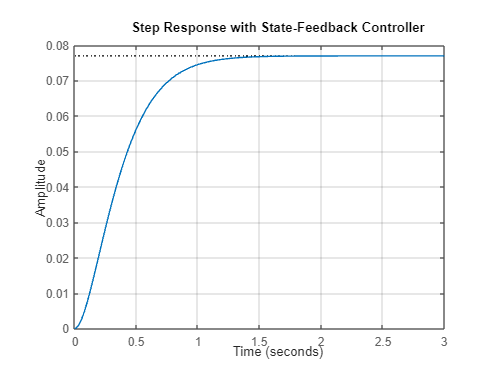

t = 0:0.01:3;
sys_cl = ss(A-B*Kc,B,C,D);
step(sys_cl,t)
grid
title('Step Response with State-Feedback Controller')

S=stepinfo(sys_cl)

S = struct with fields:
         RiseTime: 0.6399
    TransientTime: 1.1007
     SettlingTime: 1.1007
      SettlingMin: 0.0693
      SettlingMax: 0.0769
        Overshoot: 0
       Undershoot: 0
             Peak: 0.0769
         PeakTime: 1.7408


## Método 2 (servosistema) para obtención de la respuesta del sistema a una entrada escalón unitaria

AA=A-B*Kc;
BB=B*Kc(1);
CC=C;
DD=D;
sys_cl=ss(AA,BB,CC,DD)

sys_cl =
 
  A = 
               x1          x2
   x1         -10           1
   x2         -26  -2.665e-15
 
  B = 
          u1
   x1      0
   x2  25.98
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


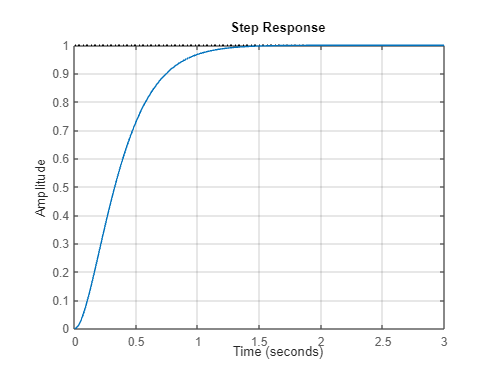

step(sys_cl,t);
grid

S=stepinfo(sys_cl)

S = struct with fields:
         RiseTime: 0.6399
    TransientTime: 1.1007
     SettlingTime: 1.1007
      SettlingMin: 0.9003
      SettlingMax: 0.9984
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9984
         PeakTime: 1.7408
